%slip8
Fs=720;
[N,wn]=buttord(10*2/Fs,20*2/Fs,3,40);
[B,A]=butter(N,wn);
ECG=load('C:\Users\dell\Desktop\ecg_data.txt');
Y=filter(B,A,ECG);
dt=1/Fs;
n=length(ECG);
T=n/Fs;
t=0:dt:T-dt;
figure();
plot(t,ECG,'r');
hold();

Current plot held


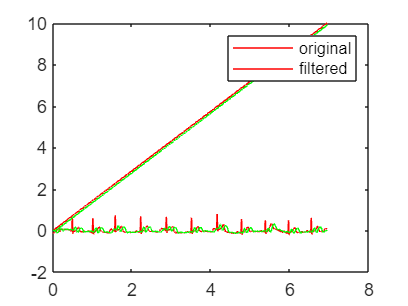

plot(t,Y,'g');
legend(['original';'filtered']);